clear

load('ecYeast_v8.6.2.mat')

id_glc = find(ismember(ecModel.rxnNames,'D-glucose exchange')); % r_1714
id_o2 = find(ismember(ecModel.rxnNames,'oxygen exchange'));  % r_1992
id_co2 = find(ismember(ecModel.rxnNames,'carbon dioxide exchange')); % r_1672

% Enzymes to be blocked
id_YML120C = find(ismember(ecModel.grRules, 'YML120C'));
id_YMR145C = find(ismember(ecModel.grRules, 'YMR145C'));
id_YDL085W = find(ismember(ecModel.grRules, 'YDL085W'));

% Set enzyme saturation
% params.sigma = 0.46

% Exchange reactions limited to physiological levels
% ecModel = setParam(ecModel,'ub','r_2033',1e-5); % Pyruvate
% ecModel = setParam(ecModel,'ub','r_1549',1e-5); % (R,R)-2,3-butanediol
% ecModel = setParam(ecModel,'ub','r_1631',1e-5); % Acetaldehyde
% ecModel = setParam(ecModel,'ub','r_1810',1e-5); % Glycine

ecModel = setParam(ecModel,'ub','r_2045',0); % Block the L-serine transport between cytoplasm and mitochondria
ecModel = setParam(ecModel,'ub','r_0659',0); % Block the conversion of isocitrate to 2-oxoglutarate in the cytoplasm via NADPH

dilution_rate = 0.1:0.025:0.38;

% Wild Type
flux_o2 = zeros(size(dilution_rate));
flux_co2 = zeros(size(dilution_rate));

% Set objective coeff of glucose to 1
ecModel = setParam(ecModel,'obj','r_1714',1); 

% Solve 
for i = 1:numel(dilution_rate)
    % Set specific growth rate to dilution rate value
    model = setParam(ecModel, 'lb','r_2111',dilution_rate(i));
    sol=solveLP(model);
    if ~isempty(sol.x)
        % Set glucose uptake to optimal value
        model = setParam(model,'lb','r_1714',sol.x(id_glc)*1.01);
        % Minimize protein pool usage
        model = setParam(model,'obj','prot_pool_exchange',1);
        sol=solveLP(model);
        flux_o2(i) = sol.x(id_o2);
        flux_co2(i) = sol.x(id_co2);
    end
end

% Knockout

% Block enzymes
for i = 1:numel(id_YML120C)
    ecModel = setParam(ecModel,'lb',id_YML120C(i),0);
    ecModel = setParam(ecModel,'ub',id_YML120C(i),0);
end

for i = 1:numel(id_YMR145C)
    ecModel = setParam(ecModel,'lb',id_YMR145C(i),0);
    ecModel = setParam(ecModel,'ub',id_YMR145C(i),0);
end

for i = 1:numel(id_YDL085W)
    ecModel = setParam(ecModel,'lb',id_YDL085W(i),0);
    ecModel = setParam(ecModel,'ub',id_YDL085W(i),0);
end

flux_o2_ko = zeros(size(dilution_rate));
flux_co2_ko = zeros(size(dilution_rate));

% Set objective coeff of glucose to 1
ecModel = setParam(ecModel,'obj','r_1714',1); 

for i = 1:numel(dilution_rate)
    % Set specific growth rate to dilution rate value
    model = setParam(ecModel, 'lb','r_2111',dilution_rate(i));
    sol=solveLP(model);
    if ~isempty(sol.x)
        % Set glucose uptake to optimal value
        model = setParam(model,'lb','r_1714',sol.x(id_glc)*1.01);
        % Minimize protein pool usage
        model = setParam(model,'obj','prot_pool_exchange',1);
        sol=solveLP(model);
        flux_o2_ko(i) = sol.x(id_o2);
        flux_co2_ko(i) = sol.x(id_co2);
    end
end

% Experimental values
exp_o2 = [3, 4, 5, 6, 6.5, 6.5, 5, 3.1, 2.7];
exp_co2 = [3.5, 4, 5.1, 6, 6.5, 8, 12.5, 16, 22];
exp_o2_ko = [2.5, 3.5, 4.6, 4.3, 4];
exp_co2_ko = [3.2, 4.2, 6.1, 10, 16];
exp_dilution = [0.1, 0.15, 0.2, 0.25, 0.28, 0.3, 0.33, 0.36, 0.38];
exp_dilution_ko = 0.1:0.05:0.3;

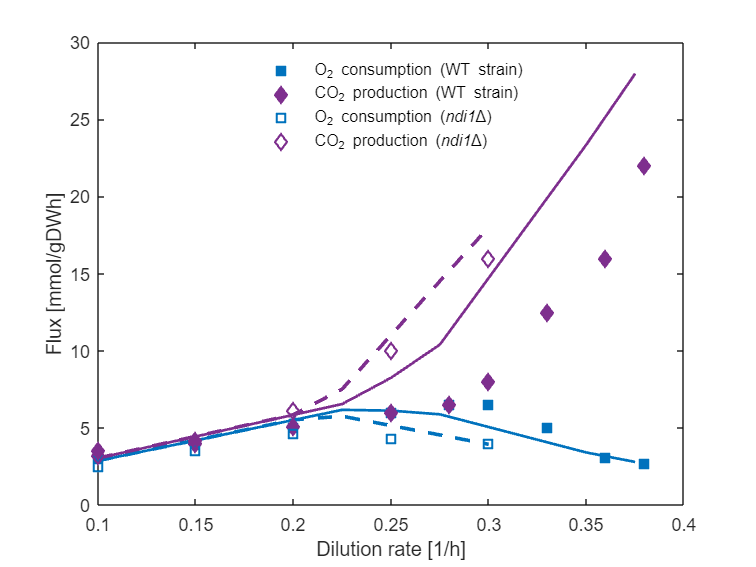

% Plots
figure
% Wild type
plot(dilution_rate,abs(flux_o2),'-',LineWidth=1.5,Color=[0 0.4470 0.7410]);
hold on
plot(dilution_rate,abs(flux_co2),'-',LineWidth=1.5,Color=[0.4940 0.1840 0.5560]);
hold on
% Knockout
plot(dilution_rate(1:floor(numel(dilution_rate)*3/4)),abs(flux_o2_ko(1:floor(numel(dilution_rate)*3/4))),Color=[0 0.4470 0.7410],LineWidth=2,LineStyle="--"); 
hold on
plot(dilution_rate(1:floor(numel(dilution_rate)*3/4)),abs(flux_co2_ko(1:floor(numel(dilution_rate)*3/4))),Color=[0.4940 0.1840 0.5560],LineWidth=2,LineStyle="--"); 
hold on
% Wild type experimental
scatter(exp_dilution,exp_o2,Marker='square',LineWidth=1.5,MarkerEdgeColor=[0 0.4470 0.7410],MarkerFaceColor=[0 0.4470 0.7410]);
hold on
scatter(exp_dilution,exp_co2,Marker='diamond',LineWidth=1.5,MarkerEdgeColor=[0.4940 0.1840 0.5560],MarkerFaceColor=[0.4940 0.1840 0.5560]);
hold on
% Knockout experimental
scatter(exp_dilution_ko,exp_o2_ko,Marker='square',LineWidth=1.5,MarkerEdgeColor=[0 0.4470 0.7410]);
hold on
scatter(exp_dilution_ko,exp_co2_ko,Marker='diamond',LineWidth=1.5,MarkerEdgeColor=[0.4940 0.1840 0.5560]);
hold off

xlabel("Dilution rate [1/h]")
ylabel("Flux [mmol/gDWh]")
xlim([0.1 0.4])

legend('', '', '', '', 'O_2 consumption (WT strain)', 'CO_2 production (WT strain)', 'O_2 consumption ({\itndi1}Δ)', 'CO_2 production ({\itndi1}Δ)', Location='north')
legend boxoff